## Metody estymacji parametrów populacji generalnej

parametr populacji 

- średnia populacji (m),

- wariancja ($\sigma^2$),

- odchylenie standardowe populacji ($\sigma$),

- wskaźnik struktury w populacji $\left(p=\frac{N_w }{N}\right)$, $N_w$  - liczba elementów posiadajacych wyróżnioną własnosć, $N$ - liczba wszystkich elementów populacji.

## Statystyki z póby

- Estymatory

**Wariancja populacji:**


$$\sigma^2 =\frac{\sum_{i=1}^N {\left(x_i -m\right)}^2 }{N}$$


N - liczba elementów populacji.

gdzie m to śrdnia populacji:


$$m=\frac{\sum_{i=1}^N x_i }{N}$$


**Wariancja próby:**

${\hat{s} }^2$=$\frac{\sum_{i=1}^n {\left(x_i -\bar{x} \right)}^2 }{n-1}$

gdzie $\bar{x}$ - średnia arytmetyczna z próby


$$\bar{x} =\frac{\sum_{i=1}^n x_i }{n}$$


n - liczebność próby.

## Przedział ufności dla średniej populacji

Założenia:

- populacja ma rozkład normalny $N\left(m,\sigma \right)$ o nieznanych parametrach,

- próba jest mała, tj. n<30,

- elementy do próby są wybierane niezależnie.

Przyjmujemy poziom ufności 1-$\alpha$

Przedział ufnosci dla średniej **m** populacji można obliczyć jako:

## $\bar{x} -t_{\frac{\alpha }{2}} \frac{\hat{s} }{\sqrt{n}}<m<\bar{x} +t_{\frac{\alpha }{2}} \frac{\hat{s} }{\sqrt{n}}$**, **

alternatywnie, w przypadku dużej próby 

$\bar{x} -t_{\frac{\alpha }{2}} \frac{s}{\sqrt{n-1}}<m<\bar{x} +t_{\frac{\alpha }{2}} \frac{s}{\sqrt{n-1}}$ ponieważ zachodzi relacja:

${\hat{s} }^2 =\frac{n}{n-1}s^{2\;}$, dla $s^2$=$\frac{\sum_{i=1}^n {\left(x_i -\bar{x} \right)}^2 }{n}$dla dużych prób (n$\ge$30).

gdzie:

n - liczebność próby,

$\bar{x}$ - średnia arytmetyczna z próby,

$\hat{s}$ - odchylenie standardowe próby,

1-$\alpha$ - przyjęty z góry poziom ufności np. 0,95,

$t_{\frac{\alpha }{2}}$ - wartość zmiennej losowej o rozkładzie t-Studenta z liczbą stopni swobody 

$k=\nu =n-1$, który "odcina" pod "prawym ogonem" krzywej gęstosci prawdopodobieństwa tego rozkładu (t-Studenta) pole o mierze $\frac{\alpha }{2}$.

Dokładność oszacowania  to połowa długości przedziału i wynosi:

## 
$$d=t_{\frac{\alpha }{2}} \frac{\hat{s} }{\sqrt{n}}$$


Przykład

clc;
clear all;
close all;
clearvars;

p = 0.95;
k=17

k = 17

alpha = 1 - p; %poziom istotności alpha=0,05
pLo = alpha/2;
pUp = 1 - alpha/2;
crit = tinv([pLo pUp], k)

crit =    -2.1098    2.1098


wartość krytyczna 2,1098

Wizualizacja

t = -5:0.1:5;
k=17

k = 17

y2 = tpdf(t,k);
figure (1)
plot(t,y2,'LineWidth',2)
hold on
grid on
t1=crit(1,2)

t1 = 2.1098

t2=crit(1,1)

t2 = -2.1098

plot(t1,tpdf(t2,k),'r*')
plot(t2,tpdf(t2,k),'r*')
a = [t1 t1];
b = [0 tpdf(t1,k)];
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
a = [t2 t2];
b = [0 tpdf(t2,k)];
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
t3 = t1:0.1:max(t);
y3 = tpdf(t3,k);
area(t3,y3,'FaceColor','b');
t4 = min(t):0.1:t2

t4 =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000


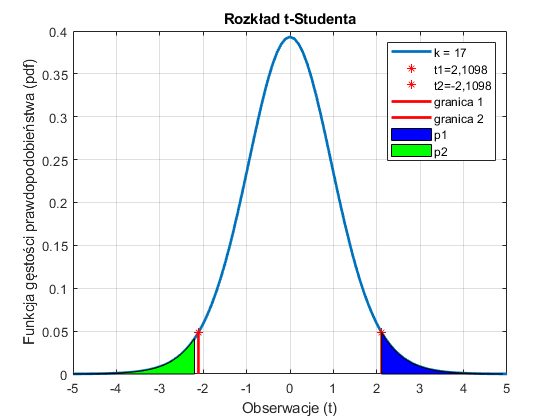

y4 = tpdf(t4,k);
area(t4,y4,'FaceColor','g');
xlabel('Obserwacje (t)')
ylabel('Funkcja gęstości prawdopodobieństwa (pdf)')
title('Rozkład t-Studenta')
legend({'k = 17','t1=2,1098','t2=-2,1098','granica 1','granica 2','p1','p2'})

Przykład:

[Ceny paliwa](https://www.autocentrum.pl/paliwa/ceny-paliw/malopolskie/pb/?s=1&order=&q=Krak%C3%B3w)

Ceny benzyny E-95:

cenypaliwa=[
5.56
5.62
5.62
5.85
5.81
5.42
5.41
5.43
5.51
5.58
5.54
5.56
5.44
5.65
5.49
5.46
5.40
5.54]  %zl/litr

cenypaliwa =     5.5600
    5.6200
    5.6200
    5.8500
    5.8100
    5.4200
    5.4100
    5.4300
    5.5100
    5.5800


Występuje mała próba danych (n=18<30)

Wartość średniej arytmetycznej z próby:


$$\mathrm{xmean}=\bar{x} =\frac{\sum_{i=1}^n x_i }{n}$$


Zastosowanie funkcji [mean](https://www.mathworks.com/help/releases/R2020a/matlab/ref/mean.html)

%web(fullfile(docroot, 'matlab/ref/mean.html'))
xmean=mean(cenypaliwa) %[zł/litr]

xmean = 5.5494

lub (sprawdzenie):

suma=0;
n=size(cenypaliwa,1)

n = 18

for i=1:n
    suma=suma+cenypaliwa(i,1);
end
if n> 0
    xmean=suma/n %[zł/litr]
end

xmean = 5.5494

Średnia cena paliwa wynosi xmean=5,55 zł/l.

Odchylenie standardowe z póby:


$$\hat{s} =\sqrt{\frac{\sum_{i=1}^n {\left(x_i -\bar{x} \right)}^2 }{n-1}}$$


Użycie funkcji [std](https://www.mathworks.com/help/releases/R2020a/matlab/ref/std.html)

%web(fullfile(docroot, 'matlab/ref/std.html'))
s=std(cenypaliwa) %[zł/litr]

s = 0.1278

lub (sprawdzenie):

licznik=0;
n=size(cenypaliwa,1)

n = 18

for i=1:n
    licznik=licznik+(cenypaliwa(i)-xmean)^2;
end
if n > 1
    s=sqrt(licznik/(n-1))
end

s = 0.1278

Odchylenie stadardowe ceny paliwa E-95 wynosi 0,13 zł/l.

Obliczamy wartość $t_{\frac{\alpha }{2}}$ (wartość krytyczna rozkładu)

zakładamy p=0,95

$\nu$=k=n-1

p=0.95

p = 0.9500

alpha=1-p

alpha = 0.0500

n=size(cenypaliwa,1)

n = 18

k=n-1 %k=18-1 =17

k = 17

pLo = alpha/2;
pUp = 1 - alpha/2;

Użycie funkcji: [tinv](https://www.mathworks.com/help/releases/R2020a/stats/tinv.html) - funkcja odwrotność dystrybuanty rozkładu t-Studenta

crit = tinv([pLo pUp], k)

crit =    -2.1098    2.1098


otrzymujemy: $t_{\frac{\alpha }{2}}$=2,1098, a dokładność oszacowania - końce poszukiwanego przedziału wynoszą:

d=crit(1,2)*(s/sqrt(size(cenypaliwa,1))) %[zł/l]

d = 0.0635

Długość szukanego przedziału (dokładność oszacowania) wynosi:

d=0,06 zł = 6 gr.

Przedział ufności ma zakres:

5,55-0,06<m<5,55+0,06

5,49<m<5,61 ,zł/l

Wniosek:

***Na poziomie ufności 95% średnia cena benzyny E-95 była wyższa niż 5,49 zł/l i niższa niż 5,61 zł/l. Precyzja tego oszacowania wynosi 0,06 zł (6 gr).***

Dla [Tarnowa](https://www.autocentrum.pl/paliwa/ceny-paliw/malopolskie/pb/?s=1&order=&q=Tarn%C3%B3w) ceny kształtują sie jako:

cenypaliwa=[
6.20
6.23
6.37
6.42
6.45
]  %zl/litr

cenypaliwa =     6.2000
    6.2300
    6.3700
    6.4200
    6.4500



xmean=mean(cenypaliwa) %[zł/litr]

xmean = 6.3340

s=std(cenypaliwa) %[zł/litr]

s = 0.1128

p=0.95

p = 0.9500

alpha=1-p

alpha = 0.0500

n=size(cenypaliwa,1)

n = 5

k=n-1 %

k = 4

pLo = alpha/2;
pUp = 1 - alpha/2;
crit = tinv([pLo pUp], k)

crit =    -2.7764    2.7764


d=crit(1,2)*(s/sqrt(size(cenypaliwa,1))) %[zł/l]

d = 0.1401

Długość szukanego przedziału (dokładność oszacowania) wynosi:

d=0,14 zł = 14 gr.

Przedział ufności ma zakres:

6,33-0,14<m<6,33+0,14

6,19<m<6,47,zł/litr

Wniosek:

***Na poziomie ufności 95% średnia cena benzyny E-95 w Tarnowie była wyższa niż 6,19 zł/l i niższa niż 6,47 zł/l. Precyzja tego oszacowania wynosi 0,14 zł (14 gr).***

## Przedział ufności dla średniej populacji o nieznanym rozkładzie, duża próba **(n**$\ge 30$**)**

Przedział ufnosci dla średniej (**m) **w populacji można obliczyć jako:

## $\bar{x} -z_{\frac{\alpha }{2}} \frac{\hat{s} }{\sqrt{n}}<m<\bar{x} +z_{\frac{\alpha }{2}} \frac{\hat{s} }{\sqrt{n}}$, 

gdzie:

n - liczebność próby,

$\bar{x}$ - średnia arytmetyczna z póby,

$\hat{s}$ - odchylenie standardowe próby,

1-$\alpha$ - przyjęty z góry poziom ufności np. 0,95,

$z_{\frac{\alpha }{2}}$ - wartość zmiennej losowej o r**ozkładzie normalnym standaryzowanym** który "odcina" pod "prawym ogonem" krzywej gęstosci prawdopodobieństwa tego rozkładu pole o mierze $\frac{\alpha }{2}$.

Dokładność oszacowania  to połowa długości przedziału i wynosi:

## 
$$d=z_{\frac{\alpha }{2}} \frac{\hat{s} }{\sqrt{n}}$$


Przykład:

dane na podstawie szeregu rozdzielczego z przedziałami klasowymi:

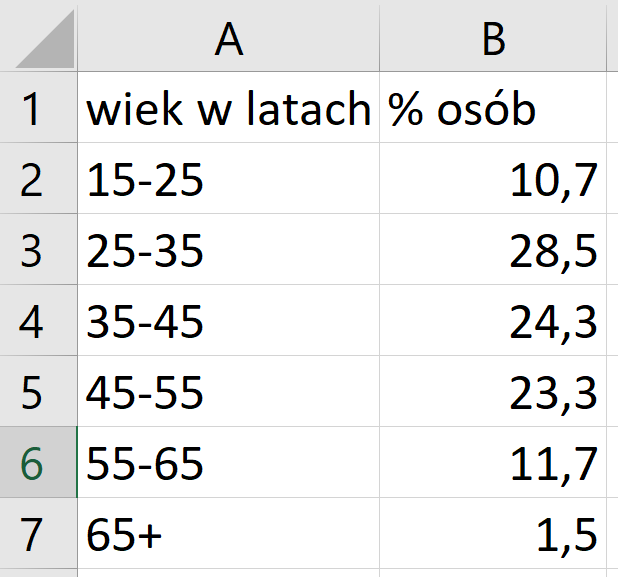

Dodatkowo wiemy, że wyniki uzyskano dla losowej próby n=1000 osób.

Chcemy oszacować średni wiek osób** aktywnych zawodowo** na poziomie ufności 95%. 

osoby=[
    10.7
    28.5
    24.3
    23.3
    11.7
    1.5
    ] % w [%] - odpowiednik n

osoby =    10.7000
   28.5000
   24.3000
   23.3000
   11.7000
    1.5000



sum(osoby)

ans = 100


wiek=[
    (15+25)/2
    (25+35)/2
    (35+45)/2
    (45+55)/2
    (55+65)/2
    (65+75)/2] %środki przedziałów - odpowiednik x

wiek =     20
    30
    40
    50
    60
    70


Wartość średnia próby obliczona jako:


$$\bar{x} =\frac{\sum_{i=1}^k {\dot{x} }_i n_i }{n}$$


gdzie:

${\dot{x} }_i$ - środek *i*-tego przedziału wieku,

$n_i$ - liczba osób w *i*-tym przedziale.

Odchylenie standardowe próby:


$$\hat{s} =\sqrt{\frac{\sum_{i=1}^k {\left({\dot{x} }_i -\bar{x} \right)}^2 n_i }{n-1}}$$


Obliczamy wartość średnią:

licznik=0

licznik = 0

k=size(wiek,1);
n=1000;
for i=1:k
    licznik=licznik+wiek(i,1)*osoby(i,1)*(n/100);
end
xmean=licznik/n

xmean = 40.1300

Średni wiek osób czynnych zawodowio wynosi 40,13 lat.

Obliczamy odchylenie standardowe:

licznik=0;
for i=1:size(wiek,1)
    licznik=licznik+(((wiek(i,1)-xmean)^2)*(osoby(i,1)*(n/100)));
end
s=sqrt(licznik/(n-1))

s = 12.4514

Odchylenie standardowe wynosi 12,45 lat

p=0.95

p = 0.9500

alpha=1-p

alpha = 0.0500


pLo = alpha/2;
pUp = 1 - alpha/2;

Odwrotność dystrybuanty rozkładu normalnego standaryzowanego.

Zastosowanie funkcji [norminv](https://www.mathworks.com/help/releases/R2020a/stats/norminv.html).

z=norminv(pUp) 

z = 1.9600

lub funkcji [makedist](https://www.mathworks.com/help/releases/R2020a/stats/makedist.html) oraz [icdf](http:// https://www.mathworks.com/help/releases/R2020a/stats/prob.normaldistribution.icdf.html)

pd = makedist('Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


z = icdf(pd,[alpha/2,1 - alpha/2])

z =    -1.9600    1.9600


Obliczamy dokładność oszacowania:

d=z(1,2)*s/sqrt(n)

d = 0.7717

Dokładność oszacowania wynosi 0,77 lat

40,13-0,77<m<40,13+0,77 lat

39,36<m<41,90 lat

Średni wiek osób aktywnych zawodowo mieści się w przedziale od 39,36 - 41,90 lat

(z 95% poziomem ufnosci).  Precyzja oszacowania wynosi 0,77 lat.

***Na poziomie ufności 95% średni wiek osób aktywnych zawodowo był wyższy niż 39,36 lat  (39 lat i 131 dni) i niższy niż 41,90 lat (41 lat i 329 dni). Precyzja tego oszacowania wynosi 0,7717 lat (282 dni).***